# **Function for cTDD - correlated Time Domain Descriptors**

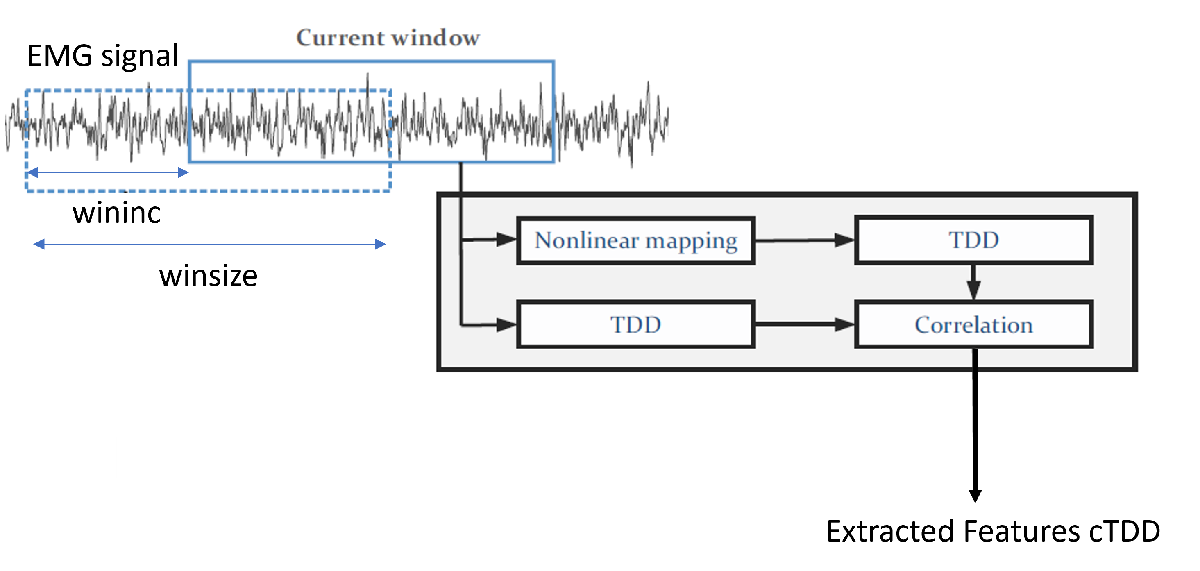

**Fig. 1: Overview of the process for computing cTTD features**

Detailed explanation of this function.

% getCTDDfeat: Correlated Time-Domain Descriptors.

## Description of getcTDDfeat_ver2

This function computes the correlated time-domain desriptors features of the signals in x, x could be made of many columns (or just one), each representing a channel/sensor. 

For example if you get 5 sec of data from 8 channels/sensors at 4000 Hz,  then x should be (20,000) x 8. A windowing scheme is used here to extract features. 

The signals in x are divided into multiple windows of size winsize and the windows are space wininc apart.

##  Inputs

    x : columns of signals

    winsize: window size (length of x)

    wininc:	spacing of the windows (winsize)

## Outputs

 feat:      correlated time domain features (6 features per channel)

function feat = getcTDDfeat_ver2(x,winsize,wininc)

    datasize = size(x,1);
    Nsignals = size(x,2);
    numwin = floor((datasize - winsize)/wininc)+1;

    % allocate memory
    feat = zeros(numwin,Nsignals*6);
    
    st = 1;
    en = winsize;

    for i = 1:numwin
   
       curwin = x(st:en,:); % current window
       
       % steps1: Extract features from original signal and a nonlinear version
       % of the current window
       ebp = KSM1(curwin);
       efp = KSM1(log(curwin.^2+eps).^2);
       
       % steps2: Correlation analysis
       num = -2.*ebp.*efp;
       den = efp.*efp+ebp.*ebp;
      
       % feature extraction goes here
       feat(i,:) = (num-den);

       st = st + wininc;
       en = en + wininc;
    end

feat = feat(1:end,:);



function Feat = KSM1(S)
% Time-domain power spectral moments (TD-PSD)
% Using Fourier relations between time domain and frequency domain to
% extract power spectral moments dircetly from time domain.
%
% Modifications
% 17/11/2013  RK: Spectral moments first created.
% 
% References
% [1] A. Al-Timemy, R. N. Khushaba, G. Bugmann, and J. Escudero, "Improving the Performance Against Force Variation of EMG Controlled Multifunctional Upper-Limb Prostheses for Transradial Amputees", 
%     IEEE Transactions on Neural Systems and Rehabilitation Engineering, DOI: 10.1109/TNSRE.2015.2445634, 2015.
% [2] R. N. Khushaba, Maen Takruri, Jaime Valls Miro, and Sarath Kodagoda, "Towards limb position invariant myoelectric pattern recognition using time-dependent spectral features", 
%     Neural Networks, vol. 55, pp. 42-58, 2014. 

Threshold = .1; % you can vary this based on your data

%% Get the size of the input signal
[samples,channels]=size(S);

% if channels>samples
%     S  = S';
%     [samples,channels]=size(S);
% end

%% Root squared zero order moment normalized
m0     = sqrt(sum(S.^2));
m0     = m0.^.1/Threshold;

% Prepare derivatives for higher order moments
d1     = diff([zeros(1,channels);diff(S)],1,1);
d2     = diff([zeros(1,channels);diff(d1)],1,1);

% Root squared 2nd and 4th order moments normalized
m2     = sqrt(sum(d1.^2)./(samples-1));
m2     = m2.^.1/Threshold;

m4     = sqrt(sum(d2.^2)./(samples-1));
m4     = m4.^.1/Threshold;

%% Sparseness
sparsi = (sqrt(abs((m0-m2).*(m0-m4))).\m0);

%% Irregularity Factor
IRF    = m2./sqrt(m0.*m4);

%% Waveform length ratio
WLR    = sum(abs(d1))./sum(abs(d2));

%% All features together
Feat   = log(abs([(m0) (m0-m2) (m0-m4) sparsi IRF WLR]));

## References:

 [1] A. A. Shaikh, A. K. Mukhopadhyay, S. Poddar and S. Samui, "Towards Robust and Accurate Myoelectric Controller Design based on Multi-objective Optimization using Evolutionary Computation," in IEEE Sensors Journal, doi: 10.1109/JSEN.2023.3347949.

 [2] R. N. Khushaba, A. Al-Ani, A. Al-Timemy, A. Al-Jumaily, "A Fusion of Time-Domain Descriptors for Improved Myoelectric Hand Control", ISCIT2016 Conference, Greece, 2016. pdf here: https://pdfs.semanticscholar.org/4730/98af39c66b0a4b541860a1f4617c036d8249.pdf

 [3] R. N. Khushaba, Maen Takruri, Jaime Valls Miro, and Sarath Kodagoda, "Towards limb position invariant myoelectric pattern recognition using time-dependent spectral features", Neural Networks, vol. 55, pp. 42-58, 2014. 